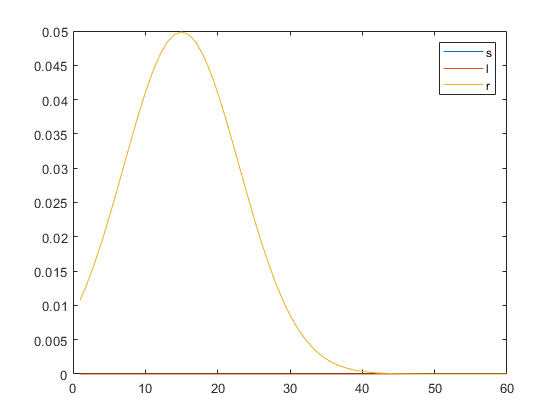

distanceRight = 50;
distanceLeft = 1000;
    if distanceLeft <= 100
        curveLeft = createBellCurve(60-distanceLeft*.3);
    else
        curveLeft = createBellCurve(-1);
        distanceLeft = 200 - distanceRight;
    end
    
    if distanceRight <= 100
        curveRight = createBellCurve(distanceRight*0.3);
    else
        curveRight = createBellCurve(-1);
        distanceRight = 200 - distanceLeft;
    end

    % turn the distance array into a movement bell curve [1x2]
    sonarCurve = createBellCurve(((60-distanceLeft*0.3) + (distanceRight*0.3))/2);
    
    plot(sonarCurve)
    hold on
    plot(curveLeft)
    plot(curveRight)
    legend("s","l","r")
    hold off